# **demo05 of Im2mesh package**

demo05 - Parameter tf_avoid_sharp_corner

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Circle

Let's start demo. Import image Circle.tif.

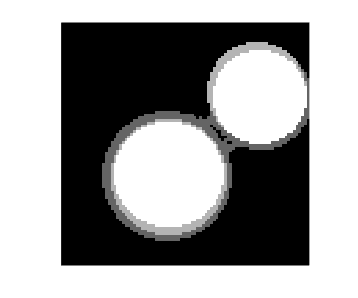

im = imread('Circle.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

opt = [];       % reset opt
opt.tf_avoid_sharp_corner = false;
opt.threshold_num_turning = 10;
opt.threshold_num_vert_Smo = 20;
opt.threshold_num_vert_Sim = 20;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          4                356                424
         10                388                896
         13                388                940


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                511                424
         10                531               1808
         20                547               2865
         29                552               2947


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                704               2929
     

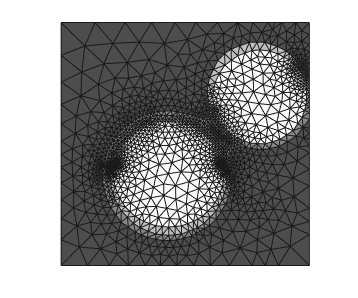

plotMeshes( vert, tria, tnum )

You can see the mesh is very dense in some region. That is induced by the sharp corner between polygonal boundaries. Let's zoom in to confirm that.

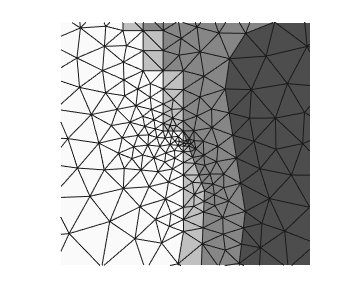

plotMeshes( vert, tria, tnum )

xlim([53.4 65.8])
ylim([30.8 42.9])

## Avoid sharp corner

We can set parameter tf_avoid_sharp_corner to true. It may help.

opt = [];       % reset opt
opt.tf_avoid_sharp_corner = true;
opt.threshold_num_turning = 10;
opt.threshold_num_vert_Smo = 20;
opt.threshold_num_vert_Sim = 20;

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                352                444
         10                383                806
         13                384                887


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                502                444
         10                522               1685
         20                529               2541
         23                530               2556


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                549               2534
     

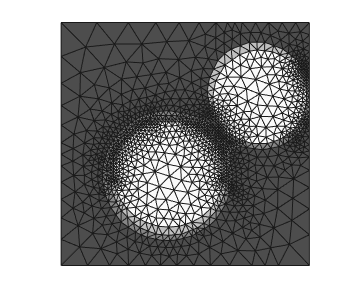


plotMeshes( vert, tria, tnum )

Zoom in

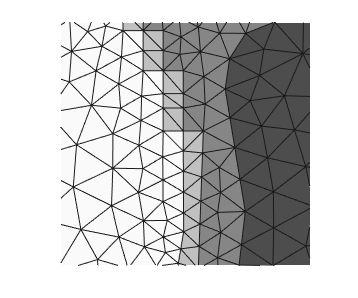

plotMeshes( vert, tria, tnum )

xlim([53.4 65.8])
ylim([30.8 42.9])

Yes, it helps.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo